# Частотная модуляция. 

# Основы.

**Для запуска скриптов необходимо корневую папку репозитория сделать рабочей папкой Matlab!**

### 1. Введение

### 2. Однотональная модуляция

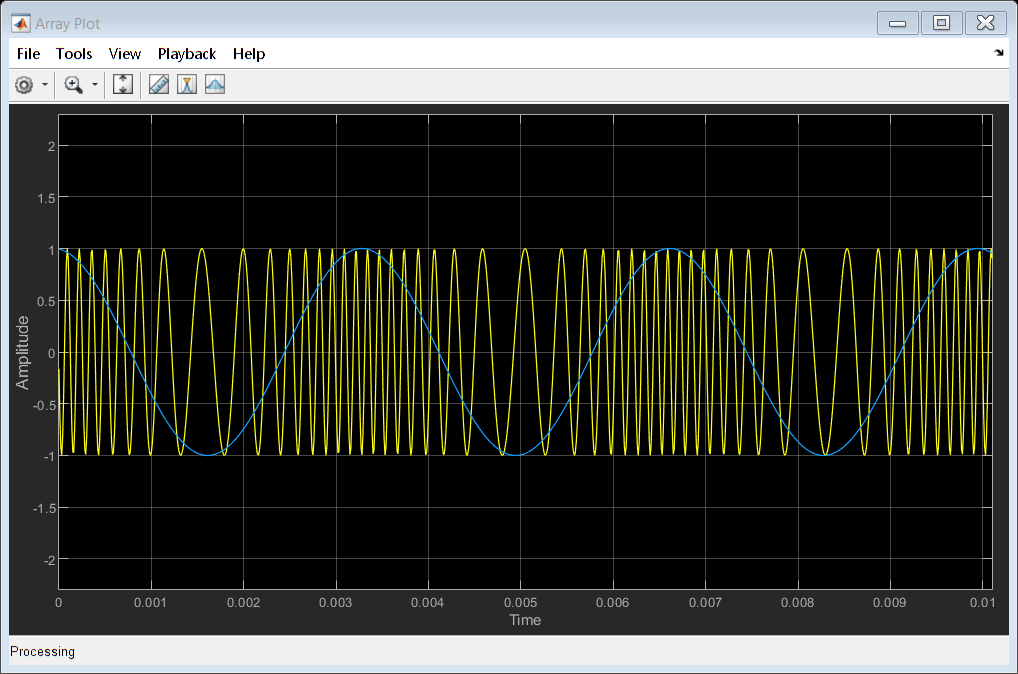

clc; clear; close all;

FrameSize = 1011;   % размер обрабатываемой за один раз пачки данных
Fs = 100e3;         % частота дискретизации (Hz)
Kf = 3e3;           % чувствительность модулятора (Hz/Volt)
Fc = 5e3;           % частота несущей (Hz)
Am = 1;             % амплитуда тонального сообщения
Fm = 300;           % частота тонального сообщения (Hz)

% генератор однотонального сигнала
% частота тона: 5 kHz
Message = dsp.SineWave(...
    'SampleRate',Fs,...
    'SamplesPerFrame',FrameSize,...
    'Frequency', Fm,...
    'Amplitude', Am ...
    );

% объект для отрисовки графиков
Plotter = dsp.ArrayPlot(...
    'PlotType', 'Line', ...
    'YLimits', [-2.3, 2.3], ...
    'SampleIncrement', 1/Fs, ...
    'XLabel', 'Time', ...
    'YLabel', 'Amplitude', ...
    'ChannelNames', {'FM Signal', 'Message'} ...
    );

% начальная фаза интегратора
InitPhase = 0;

% вычисление и вывод девиации
FreqDeviation = Kf * Am;

% вычисление индекса модуляции
ModIndex = FreqDeviation / Fm;

% запуск симуляции
for i = 1:100
    % формирование тонального сигнала
    MessageData = Message();

    % вычисление мгновенной частоты (Hz)
    freq = Fc + Kf * MessageData;
    
    % вычисление фазы в радианах c помощью интегрирования
    phase = InitPhase + 2*pi/Fs * cumsum(freq);
    
    % обновление начальной фазы интегратора
    InitPhase = phase(end);
    
    % формирование модулированного сигнала
    FmSignal = cos(phase);
    
    % вывод результатов на график
    Plotter([FmSignal, MessageData])
    
    % задержка в 0.1 секунды для лучшей визуализации
    pause(0.1)
end

disp(['Frequency deviation = ', num2str(FreqDeviation)])

Frequency deviation = 3000


disp(['Modulation index = ', num2str(ModIndex)])

Modulation index = 10


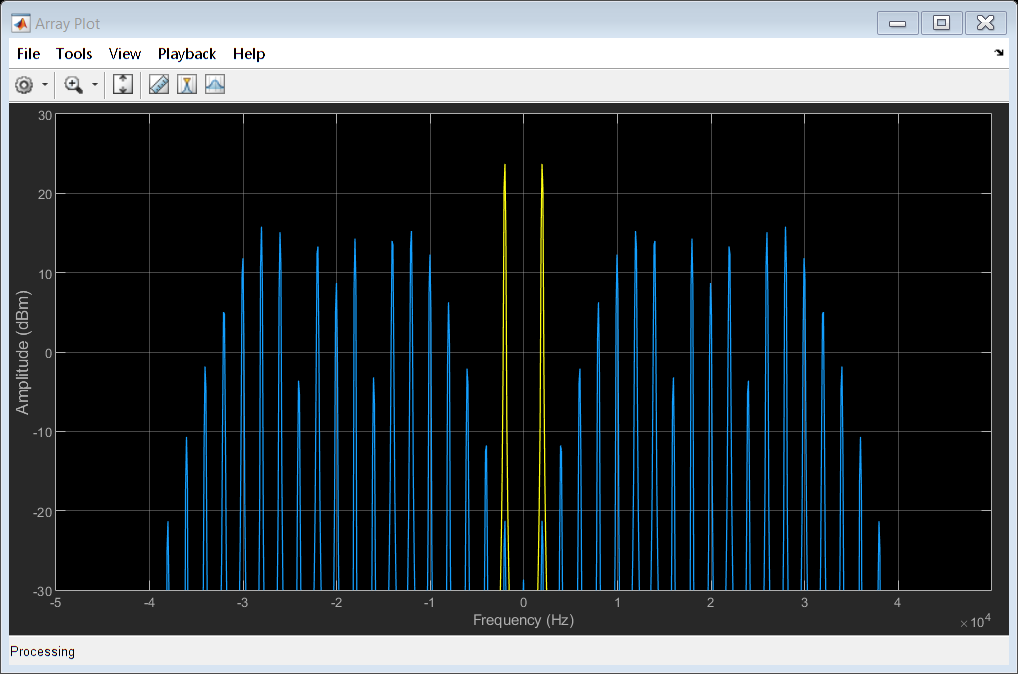

clc; clear; close all;

FrameSize = 1011;           % размер обрабатываемой за один раз пачки данных
Fs = 100e3;                 % частота дискретизации (Hz)
Kf = 10e3;   % чувствительность модулятора (Hz/Volt)
Fc = 20e3;                  % частота несущей (Hz)
Am = 1;                     % амплитуда тонального сообщения
Fm = 2e3;                   % частота тонального сообщения (Hz)

% генератор однотонального сигнала
% частота тона: 5 kHz
Message = dsp.SineWave(...
    'SampleRate',Fs,...
    'SamplesPerFrame',FrameSize,...
    'Frequency', Fm,...
    'Amplitude', Am ...
    );

% объект для вычисления спектра
SpecEstimator = dsp.SpectrumEstimator(...
    'PowerUnits','dBm', ...
    'FrequencyRange', 'centered', ...
    'SampleRate', Fs ...
    );

% объект для отрисовки графиков
Plotter = dsp.ArrayPlot(...
    'PlotType','Line', ...
    'XOffset', -Fs/2, ...
    'YLimits', [-30, 30], ...
    'XLabel', 'Frequency (Hz)', ...
    'YLabel', 'Amplitude (dBm)', ...
    'ChannelNames', {'Message', 'FM Signal'}, ...
    'SampleIncrement', Fs/FrameSize ...
    );

% начальная фаза интегратора
InitPhase = 0;

% вычисление и вывод девиации
FreqDeviation = Kf * Am;

% вычисление индекса модуляции
ModIndex = FreqDeviation / Fm;

% запуск симуляции
for i = 1:100
    % формирование тонального сигнала
    MessageData = Message();

    % вычисление мгновенной частоты (Hz)
    freq = Fc + Kf * MessageData;
    
    % вычисление фазы в радианах c помощью интегрирования
    phase = InitPhase + 2*pi/Fs * cumsum(freq);
    
    % обновление начальной фазы интегратора
    InitPhase = phase(end);
    
    % формирование модулированного сигнала
    FmSignal = cos(phase);
    
    % вычисление спектров
    Spectrums = SpecEstimator([MessageData, FmSignal]);
    
    % вывод результатов на график
    Plotter(Spectrums)
    
    % задержка в 0.1 секунды для лучшей визуализации
    pause(0.1)
end

disp(['Frequency deviation = ', num2str(FreqDeviation)])

Frequency deviation = 10000


disp(['Modulation index = ', num2str(ModIndex)])

Modulation index = 5


### 3. Модуляция несколькими тонами

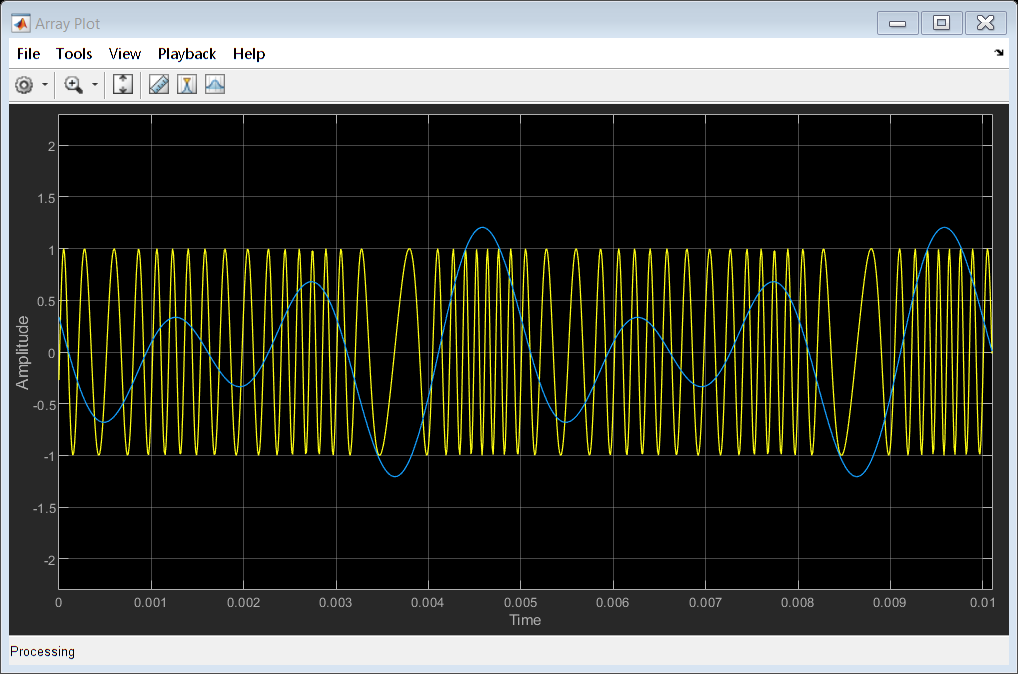

clc; clear; close all;

FrameSize = 1011;     % размер обрабатываемой за один раз пачки данных
Fs = 100e3;           % частота дискретизации (Hz)
Kf = 3e3;             % чувствительность модулятора (Hz/Volt)
Fc = 5e3;             % частота несущей (Hz)
Am = [0.1 0.5 0.7];   % амплитуды тональнов сообщения
Fm = [200 400 600];   % частоты тональнов сообщения (Hz)

% генератор сообщения из трех тонов
Message = dsp.SineWave(...
    'SampleRate', Fs, ...
    'SamplesPerFrame', FrameSize, ...
    'Frequency', Fm, ...
    'Amplitude', Am ...
    );

% объект для отрисовки графиков
Plotter = dsp.ArrayPlot(...
    'PlotType', 'Line', ...
    'YLimits', [-2.3, 2.3], ...
    'SampleIncrement', 1/Fs, ...
    'XLabel', 'Time', ...
    'YLabel', 'Amplitude', ...
    'ChannelNames', {'FM Signal', 'Message'} ...
    );

% начальная фаза интегратора
InitPhase = 0;

% вычисление и вывод девиации
FreqDeviation = Kf * sum(Am);

% запуск симуляции
for i = 1:100
    % формирование сообщения из нескольких тонов
    MessageData = Message();
    MessageData = MessageData(:,1) + MessageData(:,2) + MessageData(:,3);

    % вычисление мгновенной частоты (Hz)
    freq = Fc + Kf * MessageData;
    
    % вычисление фазы в радианах c помощью интегрирования
    phase = InitPhase + 2*pi/Fs * cumsum(freq);
    
    % обновление начальной фазы интегратора
    InitPhase = phase(end);
    
    % формирование модулированного сигнала
    FmSignal = cos(phase);
    
    % вывод результатов на график
    Plotter([FmSignal, MessageData])
    
    % задержка в 0.1 секунды для лучшей визуализации
    pause(0.1)
end

disp(['Frequency deviation = ', num2str(FreqDeviation)])

Frequency deviation = 3900


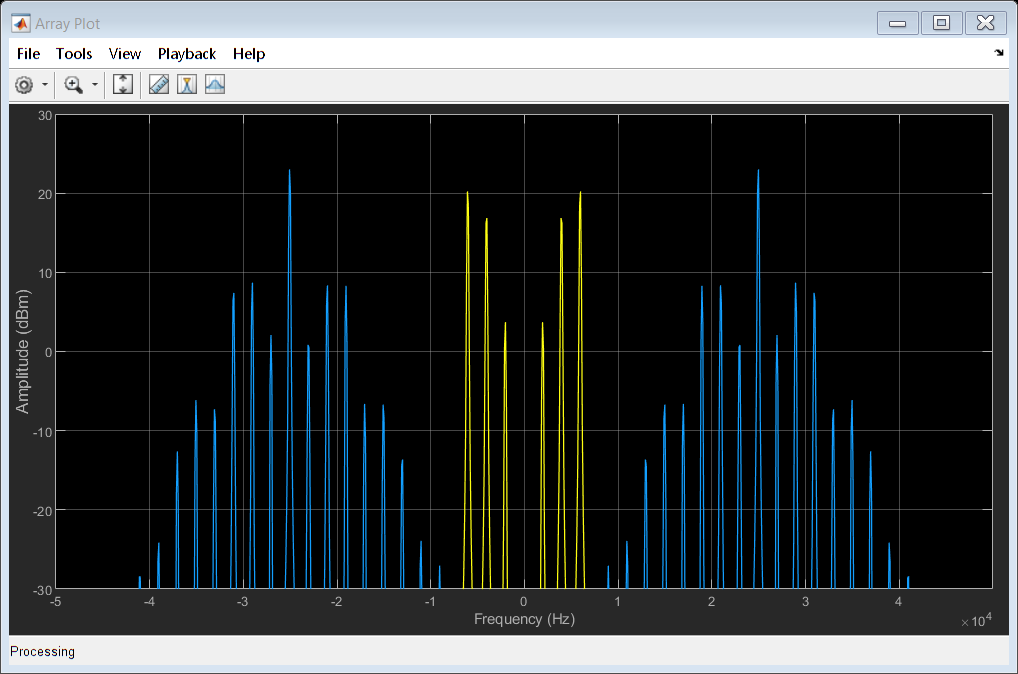

clc; clear; close all;

FrameSize = 1011;           % размер обрабатываемой за один раз пачки данных
Fs = 100e3;                 % частота дискретизации (Hz)
Kf = 3e3;   % чувствительность модулятора (Hz/Volt)
Fc = 25e3;                  % частота несущей (Hz)
Am = [0.1 0.5 0.7];         % амплитуды тональнов сообщения
Fm = [2e3 4e3 6e3];         % частоты тональнов сообщения (Hz)

% генератор сообщения из трех тонов
Message = dsp.SineWave(...
    'SampleRate', Fs, ...
    'SamplesPerFrame', FrameSize, ...
    'Frequency', Fm, ...
    'Amplitude', Am ...
    );

% объект для вычисления спектра
SpecEstimator = dsp.SpectrumEstimator(...
    'PowerUnits','dBm', ...
    'FrequencyRange', 'centered', ...
    'SampleRate', Fs ...
    );

% объект для отрисовки графиков
Plotter = dsp.ArrayPlot(...
    'PlotType','Line', ...
    'XOffset', -Fs/2, ...
    'YLimits', [-30, 30], ...
    'XLabel', 'Frequency (Hz)', ...
    'YLabel', 'Amplitude (dBm)', ...
    'ChannelNames', {'Message', 'FM Signal'}, ...
    'SampleIncrement', Fs/FrameSize ...
    );

% начальная фаза интегратора
InitPhase = 0;

% вычисление и вывод девиации
FreqDeviation = Kf * sum(Am);

% запуск симуляции
for i = 1:100
    % формирование сообщения из нескольких тонов
    MessageData = Message();
    MessageData = MessageData(:,1) + MessageData(:,2) + MessageData(:,3);

    % вычисление мгновенной частоты (Hz)
    freq = Fc + Kf * MessageData;
    
    % вычисление фазы в радианах c помощью интегрирования
    phase = InitPhase + 2*pi/Fs * cumsum(freq);
    
    % обновление начальной фазы интегратора
    InitPhase = phase(end);
    
    % формирование модулированного сигнала
    FmSignal = cos(phase);
    
    % вычисление спектров
    Spectrums = SpecEstimator([MessageData, FmSignal]);
    
    % вывод результатов на график
    Plotter(Spectrums)
    
    % задержка в 0.1 секунды для лучшей визуализации
    pause(0.1)
end

disp(['Frequency deviation = ', num2str(FreqDeviation)])

Frequency deviation = 3900


### 4. Модуляция аудиосигналом

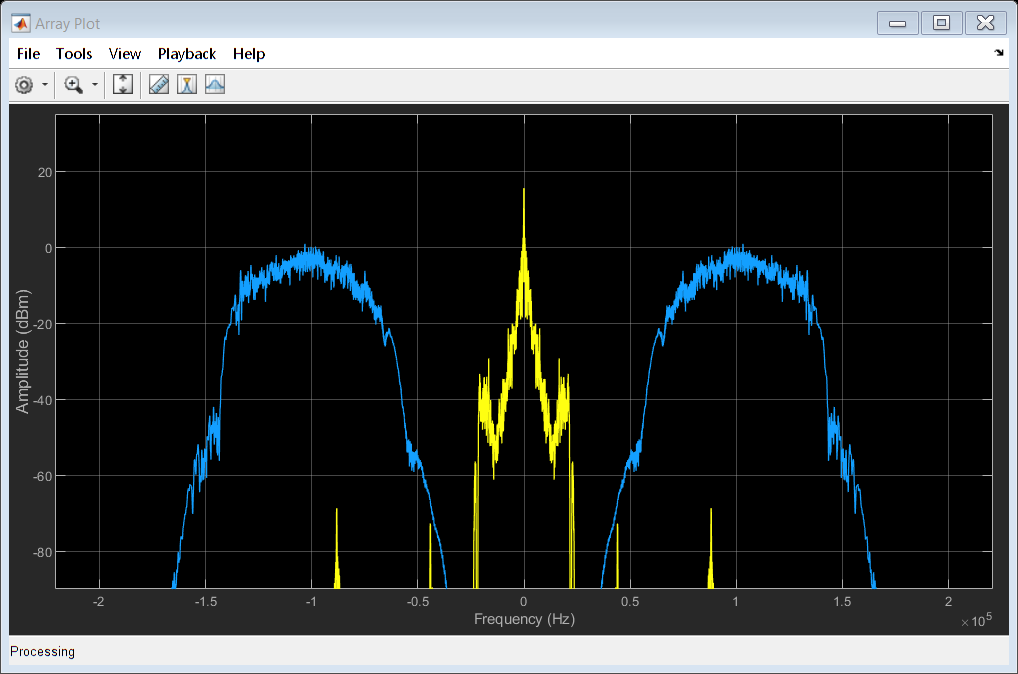

clc; clear; close all;

AudioFrameSize = 1000;      % количество отсчетов аудиофайла, получаемых за один раз
FramesNumber = 300;         % число обрабатываемых пачек данных
RateRatio = 10;             % коэффициент увеличения частоты дискретизации
Fc = 100e3;                 % частота несущей (Hz)
Kf = 40e3;   % чувствительность модулятора (Hz/Volt)

% объект для считываения отсчетов аудиофайла
AudioReader = dsp.AudioFileReader(...
    'wav/Audio_Source.wav', ...
    'SamplesPerFrame',AudioFrameSize...
    );

% дополнительные расчеты
AudioFs = AudioReader.SampleRate;               % получаем частоту дискретизации аудиосообщения
SignalFs = AudioFs * RateRatio;                 % частота дискретизации модулированного сигнала
SignalFrameSize = AudioFrameSize * RateRatio;   % количество отсчетов Ам-сигнала, получаемых за один раз

% интерполятор 
Upsampler = dsp.SampleRateConverter(...
    'Bandwidth', 40e3, ...
    'InputSampleRate',AudioFs, ...
    'OutputSampleRate', SignalFs ...
    );

% объект для вычисления спектра
SpecEstimator = dsp.SpectrumEstimator(...
    'PowerUnits','dBm',...
    'FrequencyRange','centered',...
    'SampleRate',SignalFs);

% объект для отрисовки графиков
Plotter = dsp.ArrayPlot(...
    'PlotType','Line', ...
    'XOffset', -SignalFs/2, ...
    'YLimits', [-90, 35], ...
    'XLabel', 'Frequency (Hz)', ...
    'YLabel', 'Amplitude (dBm)', ...
    'ChannelNames', {'Message', 'FM Signal'}, ...
    'SampleIncrement', SignalFs/SignalFrameSize ...
    );

% начальная фаза интегратора
InitPhase = 0;

% запуск симуляции
for i = 1:FramesNumber
    % считывание отсчетов аудиосообщения и выделение одного канала из
    % стерео сигнала
    AudioData = AudioReader();
    AudioData = AudioData(:,1);
    
    % увеличение частоты дискретизации аудиосообщения
    MessageData = Upsampler(AudioData);

    % вычисление мгновенной частоты (Hz)
    freq = Fc + Kf * MessageData;
    
    % вычисление фазы в радианах c помощью интегрирования
    phase = InitPhase + 2*pi/SignalFs * cumsum(freq);
    
    % обновление начальной фазы интегратора
    InitPhase = phase(end);
    
    % формирование модулированного сигнала
    FmSignal = cos(phase);

    % вычисление спектров
    SpectrumData = SpecEstimator([MessageData, FmSignal]);

    % вывод результатов на график
    Plotter(SpectrumData)

    % задержка в 0.1 секунды для лучшей визуализации
    pause(0.05)
end

% максимальное значение сигнала для данного аудиофайла
AudioDataMaxValue = 1;  

% вычисление и вывод девиации
FreqDeviation = Kf * AudioDataMaxValue;
disp(['Frequency deviation = ', num2str(FreqDeviation)])

Frequency deviation = 40000


% ширина спектра аудиосообщения
AudioDataBandwidth = AudioFs/2;

% вычисление и вывод индекса модуляции
ModIndex = FreqDeviation / AudioDataBandwidth;
disp(['Modulation index = ', num2str(ModIndex)])

Modulation index = 1.8141


### 5. Готовые решения Matlab

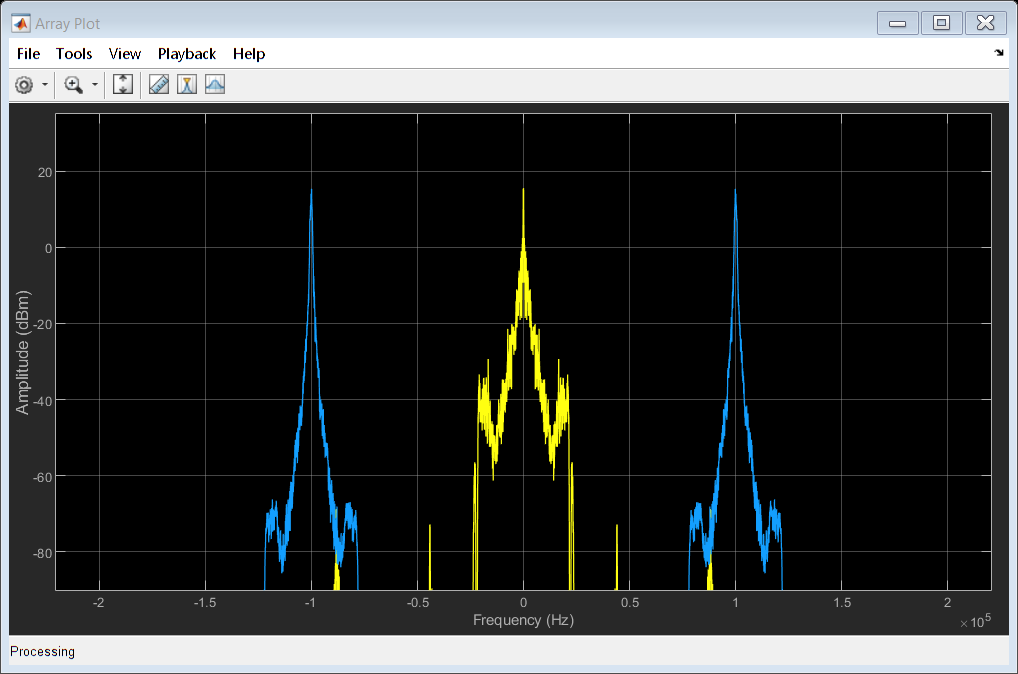

clc; clear; close all;

AudioFrameSize = 1000;      % количество отсчетов аудиофайла, получаемых за один раз
FramesNumber = 300;         % число обрабатываемых пачек данных
RateRatio = 10;             % коэффициент увеличения частоты дискретизации
Fc = 100e3;                 % частота несущей (Hz)
Kf = 1e3;   % чувствительность модулятора (Hz/Volt)

% вычисление девиации
AudioDataMaxValue = 1;
FreqDeviation = Kf * AudioDataMaxValue;

% объект для считываения отсчетов аудиофайла
AudioReader = dsp.AudioFileReader(...
    'wav/Audio_Source.wav', ...
    'SamplesPerFrame',AudioFrameSize...
    );

% дополнительные расчеты
AudioFs = AudioReader.SampleRate;               % получаем частоту дискретизации аудиосообщения
SignalFs = AudioFs * RateRatio;                 % частота дискретизации модулированного сигнала
SignalFrameSize = AudioFrameSize * RateRatio;   % количество отсчетов Ам-сигнала, получаемых за один раз

% интерполятор 
Upsampler = dsp.SampleRateConverter(...
    'Bandwidth', 40e3, ...
    'InputSampleRate',AudioFs, ...
    'OutputSampleRate', SignalFs ...
    );

% объект для вычисления спектра
SpecEstimator = dsp.SpectrumEstimator(...
    'PowerUnits','dBm',...
    'FrequencyRange','centered',...
    'SampleRate',SignalFs);

% объект для отрисовки графиков
Plotter = dsp.ArrayPlot(...
    'PlotType','Line', ...
    'XOffset', -SignalFs/2, ...
    'YLimits', [-90, 35], ...
    'XLabel', 'Frequency (Hz)', ...
    'YLabel', 'Amplitude (dBm)', ...
    'ChannelNames', {'Message', 'FM Signal'}, ...
    'SampleIncrement', SignalFs/SignalFrameSize ...
    );

% начальная фаза интегратора
InitPhase = 0;

% запуск симуляции
for i = 1:FramesNumber
    % считывание отсчетов аудиосообщения и выделение одного канала из
    % стерео сигнала
    AudioData = AudioReader();
    AudioData = AudioData(:,1);
    
    % увеличение частоты дискретизации аудиосообщения
    MessageData = Upsampler(AudioData);

    % частотная модуляция аудиосообщения
    FmSignal = fmmod(MessageData, Fc, SignalFs, FreqDeviation, InitPhase);
    
    % обновление начальной фазы в радианах несущей после модуляции
    phase = InitPhase + 2*pi/SignalFs * cumsum(Fc + Kf * MessageData);
    InitPhase = phase(end);
   
    % вычисление спектров
    SpectrumData = SpecEstimator([MessageData, FmSignal]);

    % вывод результатов на график
    Plotter(SpectrumData)

    % задержка в 0.1 секунды для лучшей визуализации
    pause(0.05)
end

### 6. Simulink модель

### Литература:

- B. P. Lathi Modern Digital and Analog Communication Systems

- R. Stewart, K. Barlee, D. Atkinson, L. Crockett Software Defined Radio using MATLAB® & Simulink and the RTL-SDR